# **Metal-Oxide Semiconductor Capacitor (MOSCAP) Electrical Characteristics**

This MATLAB LiveScript will determine and plot the MOSCAP electrical characteristics so that the optimal geometry can be found for back gating ARPES experiments. A semi-classical theory will be applied to determine the potency of the field effect and any leakage current effects. 

A schematic of our proposed sample is shown in Figure 1a, along with the expected photoemission response as a function of the back gate voltage. Our main research question is the following: How does the number density of electrons change in the δ-layer as a function of the back gate voltage?

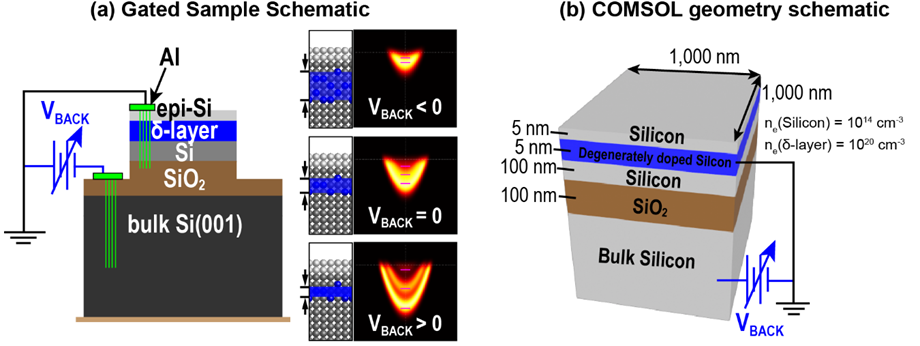

**Figure 1****: Schematic of the proposed sample.** (a) Schematic of the gated ARPES δ-layer device, with the capability of back-gated electrostatic control. A silicon-on-insulator (SOI) substrate is used, where the insulating layer acts as the dielectric for the back gate. The expected response of the conduction band (CB) states is shown to the right. (b) Proposed device stack in COMSOL, that can be treated as a MOSCAP device.

## Defining the constants

close all; clear all;
% -- Loading in constants
pp      = plot_props();
pc      = physics_constants();
% -- Extracting the material constants
si      = get_mpd_props('si');
sio2    = get_mpd_props('sio2');
al2o3   = get_mpd_props('al2o3');
% -- Defining device constants
area        = 500e-6 * 500e-6;      % area footprint of the gating [500 x 500]um^2
% -- Defining device layer values
device_epsR                 = 11.7;
device_thickness            = 100e-9;
device_resistivity          = 0.001;
device_concentration        = semi_si_res2nd(device_resistivity);
device_concentration_2d     = device_concentration.^(2/3);
[device_Ec0, device_Ev0]    = semi_si_nd2ebands(device_concentration);
% -- Defining oxide layer values
oxide_epsR                  = 3.9;
oxide_thickness             = 100e-9;
oxide_breakdown             = 1e6/0.01;
% -- Determining capacitance
capacitance     = semi_eqn_cap2(area, device_epsR, device_thickness, oxide_epsR, oxide_thickness);

## Investigating MOSCAP characteristics

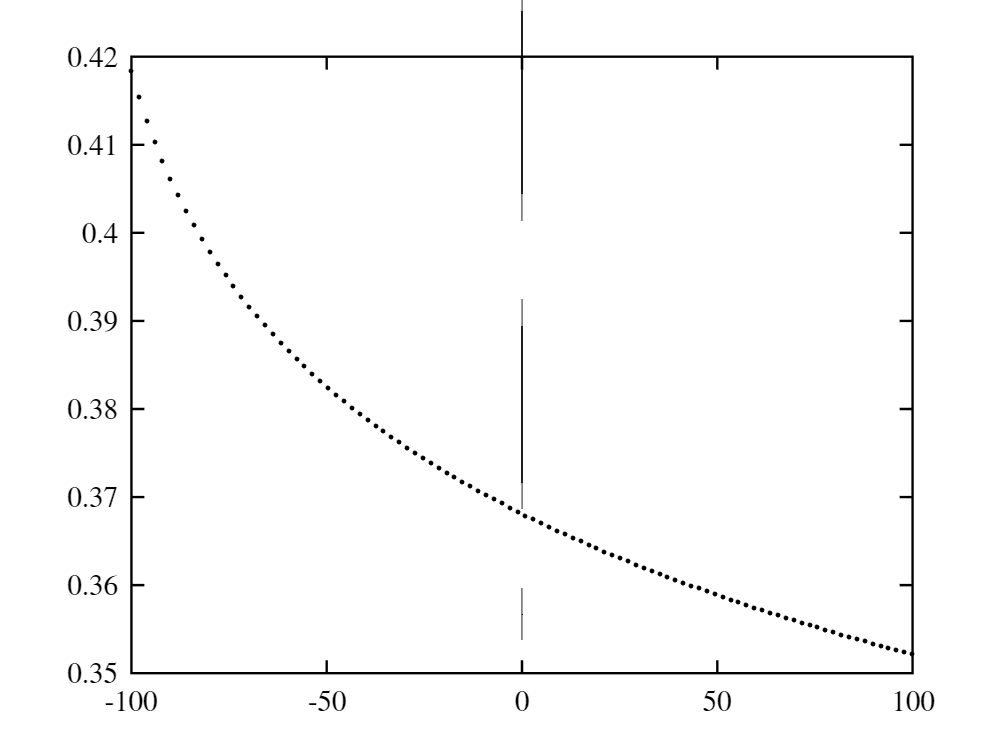

gate_voltage        = linspace(-100, 100, 1e2);
injected_charge     = capacitance.*gate_voltage./area./pc.e/10000;  % electrons / cm^-2
[final_Ec0, ~]      = semi_si_nd2ebands(device_concentration_2d+injected_charge);
figure(); hold on;
plot(gate_voltage, final_Ec0, 'k.');
gca_props();